## [Graphical Method: FOPDT to Step Test](https://apmonitor.com/pdc/index.php/Main/FirstOrderGraphical)

A first-order linear system with time delay is a common empirical description of many stable dynamic processes. The equation


$$\tau_p \frac{dy(t)}{dt} = -y(t) + K_p u\left(t-\theta_p\right)$$


has variables *y(t)* and *u(t)* and three unknown parameters.


$$K_p \quad \mathrm{= Process \; gain}$$



$$\tau_p \quad \mathrm{= Process \; time \; constant}
$$



$$\theta_p \quad \mathrm{= Process \; dead \; time}$$


Step test data are convenient for identifying an FOPDT model through a graphical fitting method. Follow the following steps when fitting the parameters $K_p$, $\tau_p$, $\theta_p$ to a step response.

- Find $\Delta y$ from step response

- Find $\Delta u
$ from step response

- Calculate $K_p = {\Delta y} / {\Delta u}$

- Find $\theta_p$, apparent dead time, from step response

- Find $0.632 \Delta y$ from step response

- Find $t_{0.632}$ for $y(t_{0.632}) = 0.632 \Delta y$ from step response

- Calculate $\tau_p = t_{0.632} - \theta_p$. This assumes that the step starts at t=0. If the step happens later, subtract the step time as well.

## Exercise

The model below is not a good fit of the process because the parameters have not been adjusted to match the data.

% calculate model with updated parameters
Km = 2.5

Km = 2.5000

taum = 3.0

taum = 3

thetam = 5.0

thetam = 5

Use the above steps to find parameters $K_p$, $\tau_p$, and $\theta_p$. Insert the updated parameters in the code and rerun the script to observe quality of the graphical fit in agreement with the simulated process data.

%specify number of points
ns = 40;
%define number of time points
t = linspace(0, 16, ns+1);
delta_t = t(2) - t(1);
tvals = t;
%define input vector
u = zeros(1, ns+1);
u(5:end) = 1;

% count = 0
yp = sim_process_data(u, delta_t, ns)

yp =          0         0         0         0         0    0.0000    0.0000    0.0006    0.0055    0.0252    0.0773    0.1807    0.3476    0.5775    0.8576    1.1667    1.4812    1.7802    2.0486    2.2781    2.4659    2.6141    2.7271    2.8109    2.8714    2.9140    2.9434    2.9633    2.9765    2.9852    2.9908    2.9943    2.9965    2.9979    2.9987    2.9993    2.9996    2.9997    2.9999    2.9999    3.0000



Km = 2.5

Km = 2.5000

taum = 3.0

taum = 3

thetam = 5.0

thetam = 5

ym = sim_model(Km,taum,thetam, ns, delta_t, u, tvals)

y1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0

ym
  Columns 1 through 12

     0     0     0     0     0     0     0     0     0     0     0     0

  Columns 13 through 24

     0     0     0     0     0     0     0     0     0     0     0     0

  Columns 25 through 36

     0     0     0     0     0     0     0     0     0     0     0     0

  Columns 37 through 41

     0     0     0     0     0

y1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0

ym
  Columns 1 through 12

     0     0     0     0     0     

ym =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0408    0.3104    0.5837    0.8229    1.0323    1.2155    1.3758    1.5162    1.6390    1.7464    1.8405    1.9228    1.9949    2.0579    2.1131    2.1614    2.2037    2.2407    2.2730    2.3014    2.3262    2.3479    2.3669    2.3835    2.3980    2.4107


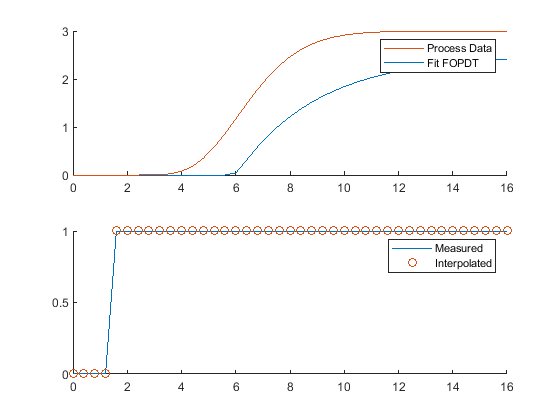


%interp1(t, u, x) will provide a value of the interpolation of the u
%function


subplot(2,1,1);
hold on
p1 = plot(t, ym);
p2 = plot(t, yp);
legend([p2, p1], {"Process Data", "Fit FOPDT"})


subplot(2,1,2);
hold on
p3 = plot(t, u);
p4 = plot(t, interp1(t, u, t), 'o');
legend([p3, p4], {"Measured", "Interpolated"})

Below are the necessary functions to run the simulation.

function dydt = process(t, y, n, u, Kp, taup)
    % arguments
    %  y[n] = outputs
    %  t    = time
    %  n    = order of the system  
    %  u    = input value
    %  Kp   = process gain
    %  taup = process time constant
%     disp('showing y')
%     disp(y)
    % equations for higher order system
    dydt = zeros(n,1);
    %size of y is determined by inital conditions
%     y = zeros(n,1); % I don't why this should be here, but it prevents y from being a 1 by 1, I don't even know what y is in this case, probably something I should find out
    % calculate derivative
    dydt(1,1) = (-y(1) + Kp * u)/(taup/n);
    for i = 2:n
%        disp('i = ')
%        disp(i)
%        disp('y is ')
%        disp(size(y))
       dydt(i,1) = (-y(i) + y(i-1))/(taup/n);
%        disp(n)
%        disp("banana")
       
    end

end

% define first-order plus dead-time approximation    
function dydt = fopdt(t, y, u, tvals, Km,taum,thetam)
    % arguments
    %  y      = output
    %  t      = time
    %  uf     = input linear function (for time shift)
    %  Km     = model gain
    %  taum   = model time constant
    %  thetam = model time constant
    % time-shift u
    try
        if (t-thetam) <= 0
            um = interp1(tvals, u, 0.0);%% IS A FUNCTION
        else
            um = interp1(tvals, u, t-thetam); %% IS A FUNCTION
        end
    catch 
        disp('Error with time extrapolation: ' + t )
        um = 0;
    end
    % calculate derivative
    dydt = (-y + Km * um)/taum;
end

% use this function or replace yp with real process data
function yp = sim_process_data(u, delta_t, ns)
    % higher order process
    n=10;       % order
    Kp=3.0;    % gain
    taup=5.0;   % time constant
    % storage for predictions or data
    yp = zeros(1,ns+1);  % process
    for i = 1:ns+1
        if i==1
            yp0 = zeros(1, n);
        end
        ts = [delta_t*(i-1),delta_t*i];
%         ts = [delta_t*(40),delta_t*41];
%         ts = [0.0 0.400];
%         count = count +   1;
%         disp('count = ')
%         disp(count)
%         disp('ts is')
%         disp(size(ts))
%         disp(ts)
        [t, y] = ode45(@(t, y) process(t, y, n, u(i), Kp, taup), ts, yp0);
        
       
        yp0 = y(end,:);
        yp(i) = y(2, n);
    end
end

% simulate FOPDT model with x=[Km,taum,thetam]
function ym = sim_model(Km,taum,thetam, ns, delta_t, u, tvals)
    % input arguments
    %Km
    %taum
    %thetam
    % storage for model values
    ym = zeros(1, (ns+1));  % model
    % initial condition
    ym(1) = 0;
    % loop through time steps    
    for i = 2:ns+1
        ts = [delta_t*(i-1),delta_t*i];
        [t, y1] = ode45(@(t, y) fopdt(t, y, u, tvals, Km,taum,thetam), ts, ym(i-1));
        disp('y1')
        disp(y1)
        %It appeats that y1 is getting the correct value the first time,
        %but then not solving then next one correctly, y1 does report 10
        %numbers, while in python it only reports 2  
        %Python first finds .0408 in column 18, matlab does it in 18
        %ode45 automatically chooses step size
        %odeint does not
%         y1 = odeint(fopdt,ym[i-1],ts,args=(uf,Km,taum,thetam));
        ym(i) = y1(end);
        disp('ym')
        disp(ym)
    end
end
